# Frequency Spectrum

### Define parameters: latitude, stratification, local depth

%Stratification
N0 = 3*2*pi/3600;
L_gm = 1300;
N2Func = @(z) N0*N0*exp(2*z/L_gm);
latitude=33;

%Depth
Lz=4000;  

### Initialize the function

im = InternalGravityWaveSpectrum(N2Func,Lz,nModes=64);

### Verify vertical variace

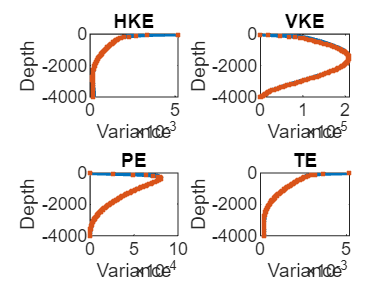

zvect = linspace(-im.Lz, 0, 100); 
energyComp = {'HKE','VKE','PE','TE'};

% Create a figure with 4 subplots
clf
figure;

% Loop over each energy component
for idx = 1:length(energyComp)
   
    [energyVariance,~,~] = im.verticalVariance(energyComp{idx}, 'zVector', zvect, 'Plot', 0);    
    
    energyVarianceFreq = zeros(1, length(zvect));
    for i = 1:length(zvect)
        energyVarianceFreq(i) = sum(im.energyAtFrequencies(energyComp{idx}, zvect(i), 'Plot', 0));
    end
    
    % Plot the variance in a subplot
    subplot(2, 2, idx);
    plot(energyVariance, zvect, LineWidth=2);
    hold on
    plot(energyVarianceFreq,zvect,'.')

    title(energyComp{idx});  
    xlabel('Variance');       
    ylabel('Depth');          

end

### Number of modes per frequency

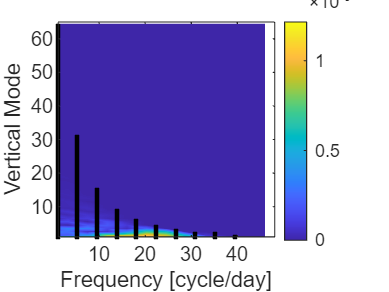

energyComp = {'HKE','VKE','PE','TE'};
[S,energyFrequency,isRepresented]= im.energyAtFrequencies('VKE',-1000, 'Plot', 0);

clf
X= (im.omegaVector*24*3600)/(2*pi);
Y= im.j;

jpcolor(X, Y, energyFrequency);
shading interp;  
colorbar;        

xlabel('Frequency [cycle/day]');
ylabel('Vertical Mode');

% Overlay black dots where isRepresented matrix has ones
hold on;
[row, col] = find(isRepresented >= 1);  
plot(X(col), Y(row), '.k');             

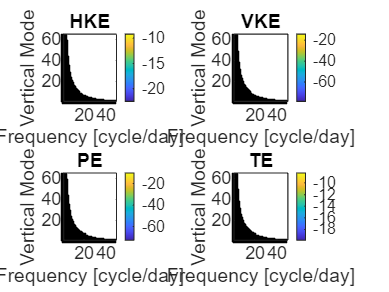

% Define energy components
energyComp = {'HKE','VKE','PE','TE'};

% Initialize figure
clf;

% Loop through each energy component
for i = 1:length(energyComp)
    % Call im.energyAtFrequencies with current energy component
    [S, energyFrequency, isRepresented] = im.energyAtFrequencies(energyComp{i}, -1000, 'Plot', 0);
    
    % Create subplot for each energy component
    subplot(2, 2, i);  % 2x2 grid of panels

    % Define X and Y
    X = (im.omegaVector * 24 * 3600) / (2 * pi);
    Y = im.j;

    % Plot energy frequency
    jpcolor(X, Y, log(energyFrequency));
    shading flat;
    colorbar;

    % Label axes
    xlabel('Frequency [cycle/day]');
    ylabel('Vertical Mode');

    % Title for each subplot based on the energy component
    title(energyComp{i});

    J =repmat(im.j',1,im.nK);
    omegajK = im.omega;

    % Overlay black dots where isRepresented matrix has ones
    % hold on;
    % [row, col] = find(isRepresented >= 1);
    % plot(X(col), Y(row), '.k');
    hold on
    scatter((omegajK*24*3600)/(2*pi),J,'k',Marker='.');


    
end

zvect2 = [-1000,-500,-300,-100,-50,-10]; 

for i = 1:length(zvect2)
        [S,~,~]=im.energyAtFrequencies('VKE',zvect2(i));
        hold on
end